clear; close all;
syms Vsmax
syms w Lqs Lds iqs ids phi;
syms Te;

Rot = @(theta) exp(1i*theta)

Rot = function_handle with value:
    @(theta)exp(1i*theta)



P = 16;
Lds = 30e-3;
Lqs = 40e-3;
phi = 1;
Vsmax = 400;
iqs = 1;
ids = 0;
w = 100*pi;
Rs = 0.22;
a = 2*pi/3;


% edqs = [-w*Lqs*iqs; w*Lds*ids+w*phi]
eds = -w*Lqs*iqs

eds = -12.5664

eqs =  w*Lds*ids + w*phi

eqs = 314.1593

Vds = Rs*ids - w*Lqs*iqs

Vds = -12.5664

Vqs = Rs*iqs + w*Lds*ids + w*phi

Vqs = 314.3793

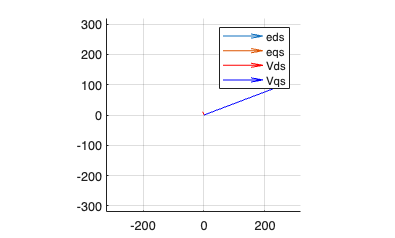


figure;
hold on; grid on;
axis([-320 320 -320 320]);
pbaspect([1 1 1])
a = -pi/2.6;

eds_plot = quiver(0, 0, eds* cos(a), eds*sin(a), displayname='eds');
eqs_plot = quiver(0, 0, eqs*-sin(a), eqs*cos(a), displayname='eqs');

Vds_plot = quiver(0, 0, Vds* cos(a), Vds*sin(a), 'r', displayname='Vds');
Vqs_plot = quiver(0, 0, Vqs*-sin(a), Vqs*cos(a), 'b', displayname='Vqs');
legend()

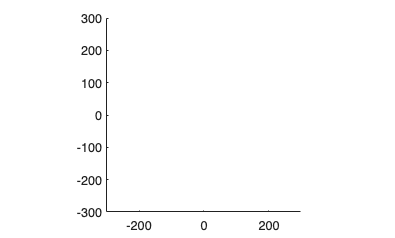




figure; hold on;
axis([-300 300 -300 300])
pbaspect([1 1 1])


quiver(0, 0, edqs(1), edqs(2))

Unrecognized function or variable 'edqs'.